## Q1)

a)

format long e
Wilkinson(5)

ans =      1    -1    -1    -1    -1
     0     1    -1    -1    -1
     0     0     1    -1    -1
     0     0     0     1    -1
     0     0     0     0     1


b)

Hamiltonian(2)

ans =      8.956384712117518e-01     5.778573463307984e-01     6.770891875973047e-01     1.566273947843791e-01
     7.309573384294533e-01     4.031403161844029e-02     1.566273947843791e-01    -3.774689555223613e-01
    -2.958871100035571e-01    -8.545692767556462e-01    -8.956384712117518e-01    -7.309573384294533e-01
    -8.545692767556462e-01     1.184448370541213e-01    -5.778573463307984e-01    -4.031403161844029e-02


**Q2)**

A=rand(8)

A =      2.010398061147072e-01     6.062687099120523e-01     2.360550732931005e-01     1.442116762372380e-01     2.551015772486168e-01     1.598484578615894e-01     3.553533315960447e-01     7.356173228133357e-01
     8.723539423565155e-01     6.774204157255943e-02     8.204315652625026e-01     7.062857318519447e-01     6.982977156162133e-02     6.722389208297781e-01     5.610817305675267e-01     7.635893576702198e-01
     4.187479305624220e-01     7.968471321759872e-01     2.387031555942687e-01     2.460404668680052e-01     3.649199883393652e-01     4.936771045769120e-01     6.112121717470125e-01     2.323635173736407e-01
     9.561001456034209e-01     7.999252020029955e-02     9.136371477665693e-01     6.885147845163880e-01     6.806010393878338e-01     1.657735115732675e-01     4.991020679354971e-01     3.283245972122641e-01
     3.388137342993913e-01     2.394964606331885e-01     4.678684351723762e-01     9.621453551889536e-01     1.759369614941201e-02     8.192411167880945e-01    

**a) Max element of each column**

 max(A)

ans =      9.561001456034209e-01     7.968471321759872e-01     9.618701665520060e-01     9.621453551889536e-01     6.835938887146491e-01     9.897236392330852e-01     9.556941748112914e-01     7.635893576702198e-01


**b) Max element of each row**


 max(A')

ans =      7.356173228133357e-01     8.723539423565155e-01     7.968471321759872e-01     9.561001456034209e-01     9.621453551889536e-01     9.897236392330852e-01     6.965656341494535e-01     9.556941748112914e-01


**c) Overall max element **

max(max(A))

ans =      9.897236392330852e-01


**Rows and columns of the matrix that has elemts >0.25**

[row, col] = find(A > 0.25);

disp([row, col] );

     2     1
     3     1
     4     1
     5     1
     6     1
     7     1
     1     2
     3     2
     6     2
     2     3
     4     3
     5     3
     6     3
     7     3
     8     3
     2     4
     4     4
     5     4
     7     4
     8     4
     1     5
     3     5
     4     5
     8     5
     2     6
     3     6
     5     6
     6     6
     7     6
     8     6
     1     7
     2     7
     3     7
     4     7
     5     7
     6     7
     7     7
     8     7
     1     8
     2     8
     4     8
     5     8
     6     8
     7     8
     8     8



**3) Generating a magic Square matrix of size 5x5**


% change the size here
B=magic(5)

B =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


b=flip(B)

b =     11    18    25     2     9
    10    12    19    21     3
     4     6    13    20    22
    23     5     7    14    16
    17    24     1     8    15


**Sum of columns of B**

sum(B)

ans =     65    65    65    65    65


**Sum of rows of B**

sum(B')'

ans =     65
    65
    65
    65
    65


**sum of diagnal elements**


sum(diag(B))

ans =     65


**Sum of antidiagonal elements**

sum(diag(b))

ans =     65


**4) magic sqaure matrices of size 3,4,5**

for n= 3:1:5
    A=magic(n)
    sum(A)%sum of rows
    sum(A')'%sum of columns
    sum(diag(A))%sum of diagonal elements
    sum(diag(flipud(A)))%sum of anti diagonal elements
    rank(A)
    p=randperm(n)
    q=randperm(n)
    A=A(p,q)%transforms a through a permuattion of rows and columns
    sum(A)
    sum(A')'
    sum(diag(A))
    sum(diag(flipud(A)))
    rank(A)
end

A =      8     1     6
     3     5     7
     4     9     2


ans =     15    15    15


ans =     15
    15
    15


ans =     15


ans =     15


ans =      3


p =      1     3     2


q =      3     1     2


A =      6     8     1
     2     4     9
     7     3     5


ans =     15    15    15


ans =     15
    15
    15


ans =     15


ans =     12


ans =      3


A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


ans =     34    34    34    34


ans =     34
    34
    34
    34


ans =     34


ans =     34


ans =      3


p =      1     3     2     4


q =      2     1     4     3


A =      2    16    13     3
     7     9    12     6
    11     5     8    10
    14     4     1    15


ans =     34    34    34    34


ans =     34
    34
    34
    34


ans =     34


ans =     34


ans =      3


A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


ans =     65    65    65    65    65


ans =     65
    65
    65
    65
    65


ans =     65


ans =     65


ans =      5


p =      2     1     3     4     5


q =      4     1     5     3     2


A =     14    23    16     7     5
     8    17    15     1    24
    20     4    22    13     6
    21    10     3    19    12
     2    11     9    25    18


ans =     65    65    65    65    65


ans =     65
    65
    65
    65
    65


ans =     90


ans =     40


ans =      5


- **We can observe from the above that the rank of the odd magic square matrices is same as their size.**

- **Also using the randperm commands the output did not change.**

**4)**

**c)**

A=magic(4)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


null(A)

ans =     -2.236067977499792e-01
    -6.708203932499368e-01
     6.708203932499367e-01
     2.236067977499792e-01


null(A,'r')

ans =     -1
    -3
     3
     1


rref(A)

ans =      1     0     0     1
     0     1     0     3
     0     0     1    -3
     0     0     0     0


**No. of linearly independent columns in A are 3**

**5)**

A=magic(5)

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


B=A^-1

B =     -4.935897435897436e-03     5.115384615384615e-02    -3.538461538461538e-02     1.153846153846149e-03     3.397435897435900e-03
     4.314102564102563e-02    -3.730769230769230e-02    -4.615384615384618e-03     1.269230769230769e-02     1.474358974358976e-03
    -3.025641025641026e-02     3.076923076923077e-03     3.076923076923080e-03     3.076923076923076e-03     3.641025641025641e-02
     4.679487179487185e-03    -6.538461538461540e-03     1.076923076923077e-02     4.346153846153845e-02    -3.698717948717949e-02
     2.756410256410258e-03     4.999999999999994e-03     4.153846153846154e-02    -4.499999999999998e-02     1.108974358974358e-02


C=1./A

C =      5.882352941176471e-02     4.166666666666666e-02     1.000000000000000e+00     1.250000000000000e-01     6.666666666666667e-02
     4.347826086956522e-02     2.000000000000000e-01     1.428571428571428e-01     7.142857142857142e-02     6.250000000000000e-02
     2.500000000000000e-01     1.666666666666667e-01     7.692307692307693e-02     5.000000000000000e-02     4.545454545454546e-02
     1.000000000000000e-01     8.333333333333333e-02     5.263157894736842e-02     4.761904761904762e-02     3.333333333333333e-01
     9.090909090909091e-02     5.555555555555555e-02     4.000000000000000e-02     5.000000000000000e-01     1.111111111111111e-01


D=A.^-1

D =      5.882352941176471e-02     4.166666666666666e-02     1.000000000000000e+00     1.250000000000000e-01     6.666666666666667e-02
     4.347826086956522e-02     2.000000000000000e-01     1.428571428571428e-01     7.142857142857142e-02     6.250000000000000e-02
     2.500000000000000e-01     1.666666666666667e-01     7.692307692307693e-02     5.000000000000000e-02     4.545454545454546e-02
     1.000000000000000e-01     8.333333333333333e-02     5.263157894736842e-02     4.761904761904762e-02     3.333333333333333e-01
     9.090909090909091e-02     5.555555555555555e-02     4.000000000000000e-02     5.000000000000000e-01     1.111111111111111e-01


- **B is the inverse of A whereas the matrices C and D are inversing each element Of A So, B!=C and C=D**

**6)**

p = randi([1, 10], 1, 5)

p =     10     4    10     1     3


**This command multiplies the elements of vector p with n-1,n-2.....0 respectively which gives the coefficients of the derivative of the polynomial.**

(length(p)-1:-1:0) .* p

ans =     40    12    20     1     0


**7)**

**a)**

m=15;
v=ones(m,1);
v2 =[1];
x=diag(v,1)+diag(v2,-15)+diag(v2,15)+diag(v,-1)-2.*(eye(16))

x =     -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0


**b)**

n = 16;
x = toeplitz([-2 1 zeros(1,n-2)]);
x(1,end) = 1;
x(end,1) = 1;
display(x)

x =     -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0


**c)**

A = toeplitz([1; zeros(7,1)], 1:8)

A =      1     2     3     4     5     6     7     8
     0     1     2     3     4     5     6     7
     0     0     1     2     3     4     5     6
     0     0     0     1     2     3     4     5
     0     0     0     0     1     2     3     4
     0     0     0     0     0     1     2     3
     0     0     0     0     0     0     1     2
     0     0     0     0     0     0     0     1


**d)**

format rat
H=toeplitz(1./(1:8))

H =        1              1/2            1/3            1/4            1/5            1/6            1/7            1/8     
       1/2            1              1/2            1/3            1/4            1/5            1/6            1/7     
       1/3            1/2            1              1/2            1/3            1/4            1/5            1/6     
       1/4            1/3            1/2            1              1/2            1/3            1/4            1/5     
       1/5            1/4            1/3            1/2            1              1/2            1/3            1/4     
       1/6            1/5            1/4            1/3            1/2            1              1/2            1/3     
       1/7            1/6            1/5            1/4            1/3            1/2            1              1/2     
       1/8            1/7            1/6            1/5            1/4            1/3            1/2            1       


**8)**

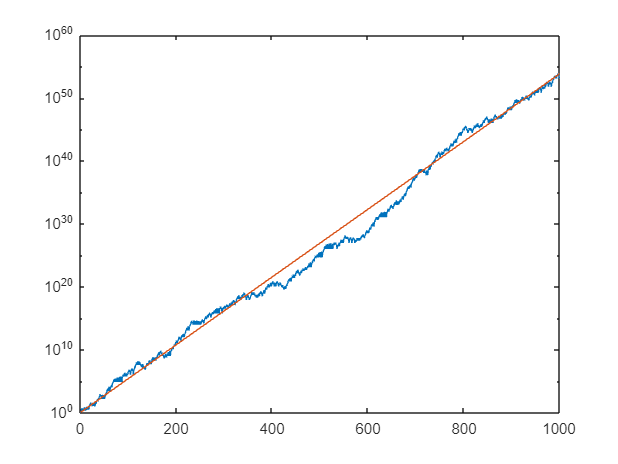

clear
rand('state',1000)
x=[1,2];
for n=2:999, x(n+1) = x(n)+sign( rand-0.5)*x(n-1); end
semilogy (1:1000, abs(x))
c =1.13198824;
hold on
semilogy(1:1000, c.^ [1:1000])
hold off

**Here, we can see the sequence growing along or below the c^n line, verifying the assertion numerically.**

**9)**

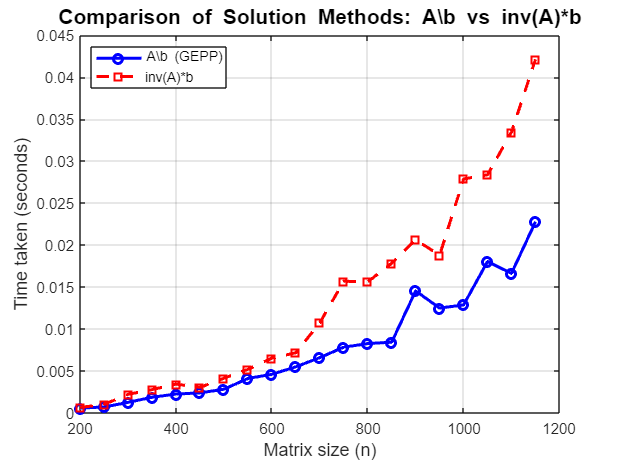

ma()

**Here we can see that GEPP is more efficient as it takes less time compared to inv(A)*B.**

# Functions

function[W] = Wilkinson(n)
  W=triu(eye(n)-ones(n))+eye(n);
end
function[H]= Hamiltonian(n)
 H11=randn(n);
 a=randn(n);
 b=randn(n);
 H=[H11 (a + a') / 2
    (b + b') / 2 -H11'];
end
function ma()
    s = 200:50:1150;
    num = length(s);
    t_div = zeros(1, num);
    t_inv = zeros(1, num);
    
    for i = 1:num
        n = s(i);
        A = rand(n);
        b = rand(n, 1);
        tic;
        x1 = A\b;
        t_div(i) = toc;
        tic;
        x2 = inv(A)*b;
        t_inv(i) = toc;
    end
    
    figure;
    semilogy(s, t_div, 'b-o', 'LineWidth', 2); hold on;
    semilogy(s, t_inv, 'r--s', 'LineWidth', 2);
    grid on;
    
    xlabel('Matrix size (n)', 'FontSize', 12);
    ylabel('Time taken (seconds)', 'FontSize', 12);
    title('Comparison of Solution Methods: A\\b vs inv(A)*b', 'FontSize', 14);
    legend('A\\b (GEPP)', 'inv(A)*b', 'Location', 'northwest');
end

